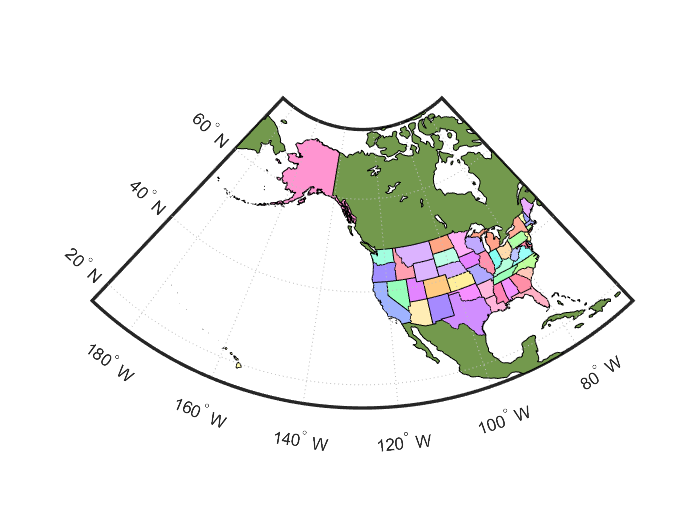

clear
% Map of the United States of America
ax = worldmap('USA');
load coast
geoshow(ax, lat, long,...
    'DisplayType', 'polygon', 'FaceColor', [.45 .60 .30])
states = shaperead('usastatehi', 'UseGeoCoords', true);
faceColors = makesymbolspec('Polygon',...
    {'INDEX', [1 numel(states)], 'FaceColor', polcmap(numel(states))});
geoshow(ax, states, 'DisplayType', 'polygon', 'SymbolSpec', faceColors)

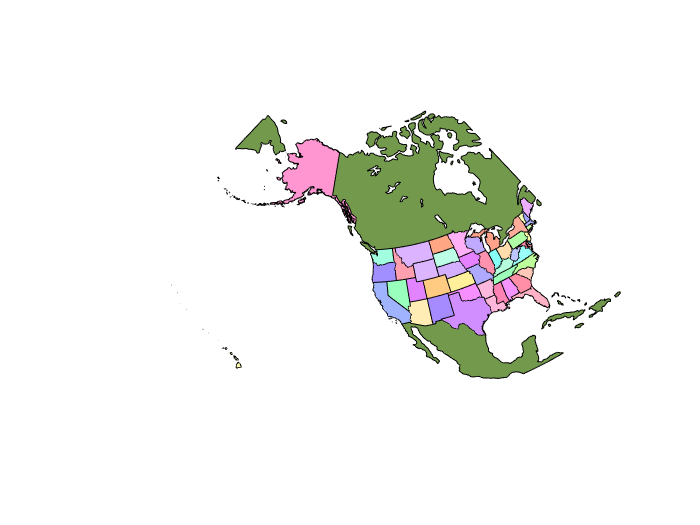

% 去除图框、经纬度网格线、经纬度标度
framem off;
gridm off;
mlabel off;
plabel off;